# 音波の基礎

## MATLAB関数

- figure

- plot

- hold on

- xlabel

- ylabel

- title

- sound

- for

- linspace

- length

- ones

- fliplr

## サイン波コサイン波

演習: [この図](https://gyazo.com/d7a5ea58590b3443ccd2c699934cc562)（サイン波とコサイン波）をMatlabで書いてみよう（位相は-3πから3π, 振幅は1.0）

% データの作成
a =  1.0; % 振幅
x =  (-3*pi):0.1:(3*pi); %  -3πから3πまで0.1刻み
y1 = a*sin(x); % サイン波
y2 = a*cos(x); % コサイン波

% データのプロット
figure;
plot(x, y1, 'c--', 'LineWidth', 1);
hold;

現在のプロットをホールドしました


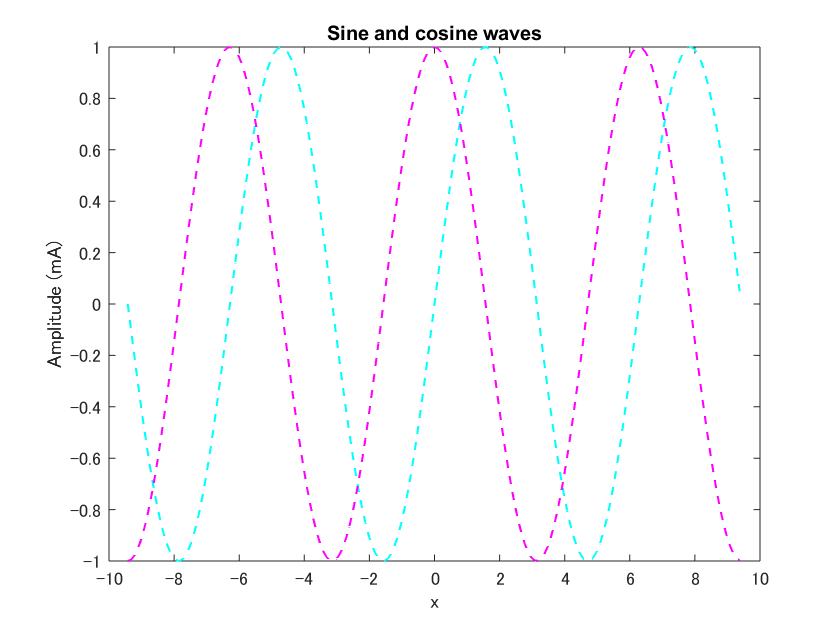

plot(x, y2, 'm--', 'LineWidth', 1);
xlabel('x', 'FontName', 'Helvetica');
ylabel('Amplitude (mA)', 'FontName', 'Helvetica');
title('Sine and cosine waves', 'FontName', 'Helvetica', 'FontWeight', 'bold');

応用演習：プロットの色や形、線の太さ、ラベルやタイトルのフォントサイズを変更し、自分ならではの美しいプロットを作成して下さい。

ヒント：[figure](https://jp.mathworks.com/help/matlab/ref/figure.html), [plot](https://jp.mathworks.com/help/matlab/ref/plot.html), [hold](https://jp.mathworks.com/help/matlab/ref/hold.html), [xlabel](https://jp.mathworks.com/help/matlab/ref/xlabel.html), [ylabel](https://jp.mathworks.com/help/matlab/ref/ylabel.html), [legend](https://jp.mathworks.com/help/matlab/ref/legend.html), [title](https://jp.mathworks.com/help/matlab/ref/title.html)

## 波の標本化（サンプリング）

演習: Matlab上で、周波数４Hz のサイン波を、サンプリング周波数 80 Hz で２秒間プロットしてみよう。

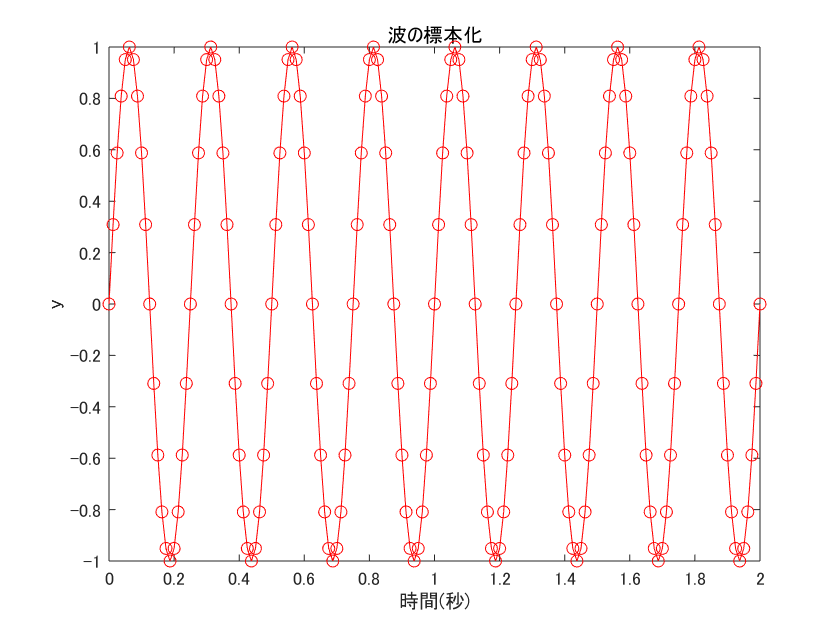

% データの作成
a =  1.0;           % 振幅
f =  4.0;           % 周波数
Fs = 80;            % サンプリング周波数、１秒間に何ポイント標本化するか。
d = 2.0;            % サイン波の長さ（秒）
t = 0:1/Fs:d;       % 1/Fsの刻み幅で時間軸を作成
y = a*sin(2*pi*f*t);   % サイン波の作成

% データのプロット
figure; 
plot(t,y,'ro-'); 
xlabel('時間(秒)');
ylabel('y');
title('波の標本化')

演習: サンプリング周波数を変えながら、周波数４Hz のサイン波をMATLAB上でプロットし、波形がどのように変わるか観察してみよう。

## 440Hz音の作成

演習：Matlab上で、周波数440Hz のサイン波を、サンプリング周波数 48000 Hz で２秒間プロットしてみよう。

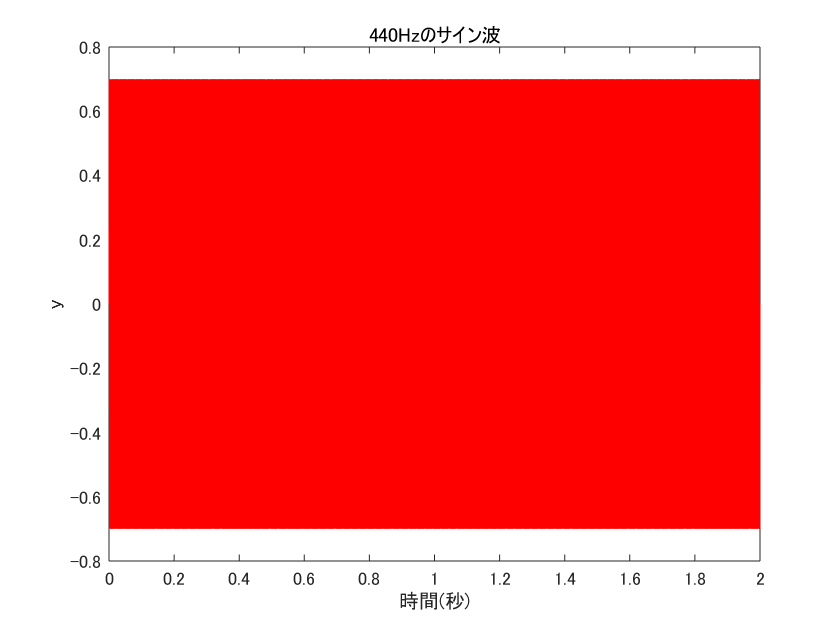

% データの作成
Fs = 48000;     % サンプリング周波数
f = 440.0;      % 周波数 
a = 0.7;        % 振幅
d = 2.0;        % データ長（秒）
t = 0:1/Fs:d;   % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
y = a*sin(2*pi*f*t); % サイン波の作成

% データのプロット
figure; 
plot(t,y,'r'); 
xlabel('時間(秒)');
ylabel('y');
title('440Hzのサイン波');


% サウンドの再生
sound(y, Fs);

ヒント： [sound](https://jp.mathworks.com/help/matlab/ref/sound.html)

## 様々な音の作成

演習：周波数や振幅を変えた時、音がどのように変化するか試してみましょう。

% データの作成
Fs = 48000;    % サンプリング周波数
f = 1600 % 周波数

f = 1600

a = 0.4 % 振幅

a = 0.4000

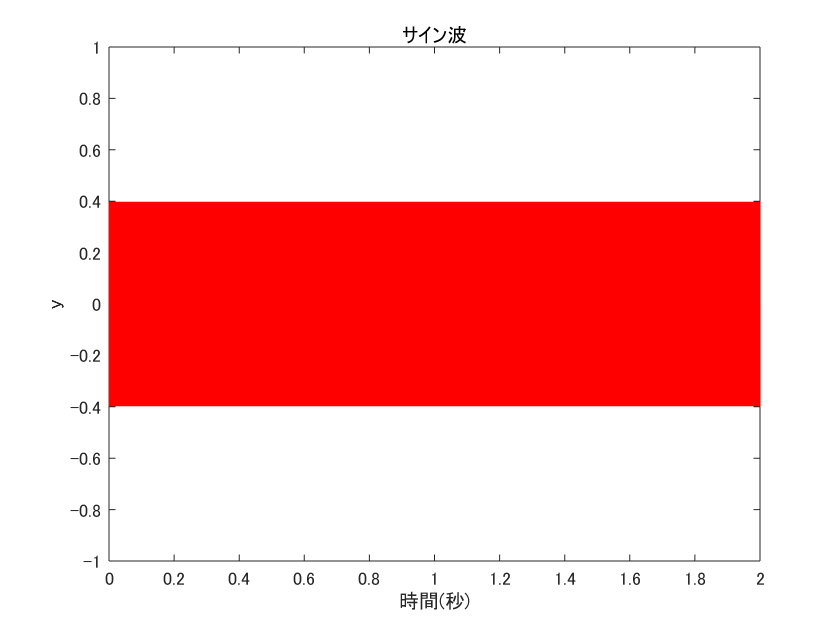

d = 2.0; % データ長(秒)
t = 0:1/Fs:d; % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
y = a*sin(2*pi*t*f); % サイン波の作成

% データのプロット
figure; 
plot(t,y,'r-');
ylim([-1 1]);
xlabel('時間(秒)');
ylabel('y');
title('サイン波')


% サウンドの再生
sound(y, Fs);

## ２つのサイン波の合成

演習：２つのサイン波の周波数や振幅を変えて合成した時、音がどのように変化するか試してみましょう。

% データの作成
Fs = 48000; % サンプリング周波数
f1 = 330 % １つ目のサイン波の周波数

f1 = 330

f2 = 440 % ２つ目のサイン波の周波数

f2 = 440

a1 = 0.6 % １つ目のサイン波の振幅

a1 = 0.6000

a2 = 1 % ２つ目のサイン波の振幅

a2 = 1

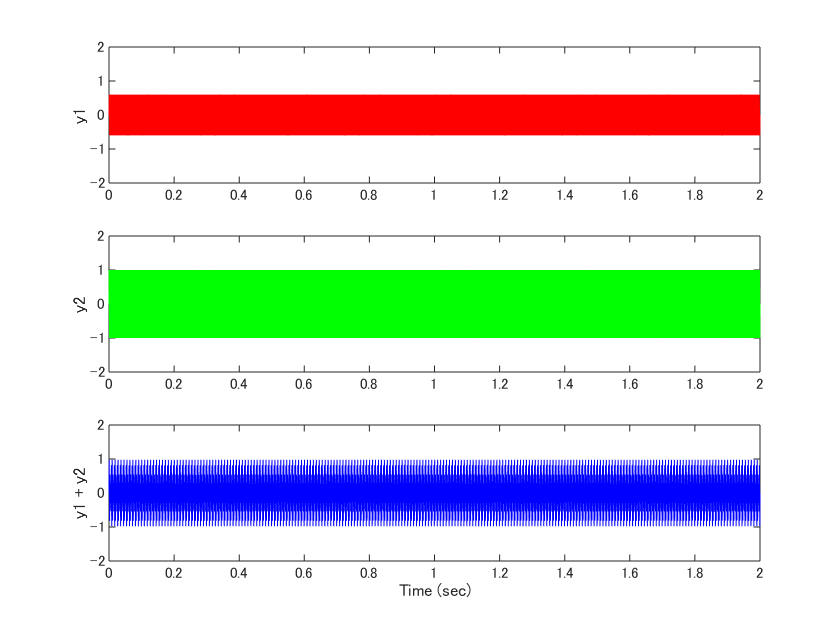

d = 2.0;  % データ長(秒)
t =  0:1/Fs:d; % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
y1 = a1*sin(2*pi*t*f1); % １つ目のサイン波の作成
y2 = a2*sin(2*pi*t*f2); % ２つ目のサイン波の作成
y = (1/(a1+a2))*(y1+y2); % サイン波の合成

% データのプロット
figure;
subplot(3,1,1); plot(t,y1,'r-'); ylabel('y1'); ylim([-2 2]);
subplot(3,1,2); plot(t,y2,'g-'); ylabel('y2'); ylim([-2 2]);
subplot(3,1,3); plot(t,y,'b-'); ylabel('y1 + y2'); ylim([-2 2]);
xlabel('Time (sec)');


% サウンドの再生
sound(y, Fs);

## 周波数が徐々に高くなる純音の作成

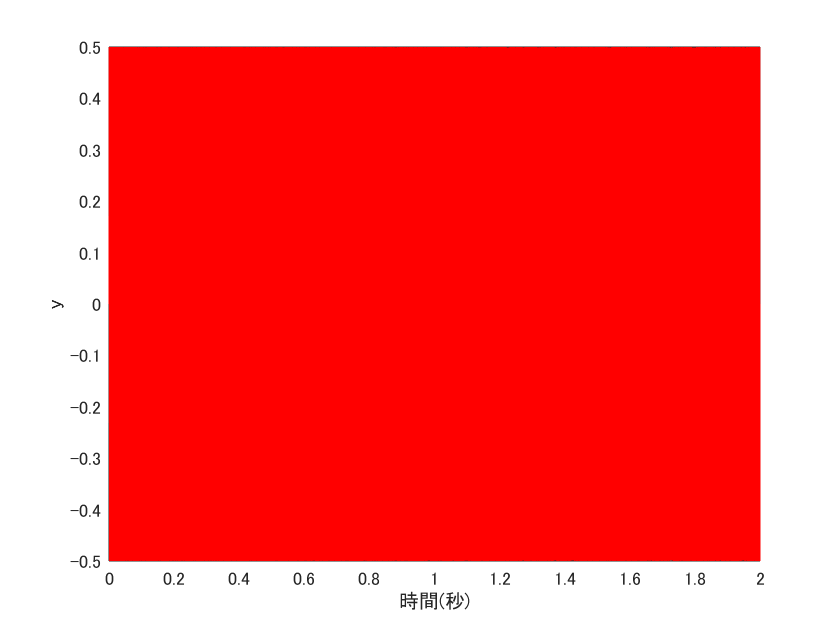

% データの作成
Fs = 48000; % サンプリング周波数
a =  0.5; % 振幅
d =  0.2; % データ長（秒）
ti = 0:1/Fs:d; % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
y = []; % 初期化
for f = 200:20:400
    yi = a*sin(2*pi*f*ti);
    yi = yi(1:end-1);
    y =[y, yi];
end
% f = linspace(440, 880, length(ti))
% y = a*sin(2*pi*f.*ti)
t = [0:length(y)-1]/Fs; % 時間

% データのプロット
figure; 
plot(t,y,'r-'); 
xlabel('時間(秒)');
ylabel('y');


% サウンドの再生
sound(y, Fs);

ヒント：[for](https://jp.mathworks.com/help/matlab/ref/for.html)

## 窓関数を通した純音の作成

% データの作成
Fs = 48000;      % サンプリング周波数
f =  440;        % 周波数 
a =  1.0;        % 振幅
d =  2.0;        % データ長（秒）
t =  0:1/Fs:d;   % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
y =  a*sin(2*pi*f*t); % サイン波の作成
n = length(y);   % サイン波のデータポイント数

% 窓関数の作成
wd = 0.05            % 窓関数の長さ（秒） 

wd = 0.0500

nw = round(Fs*wd)   % 立ち上がり窓のデータ数         

nw = 2400

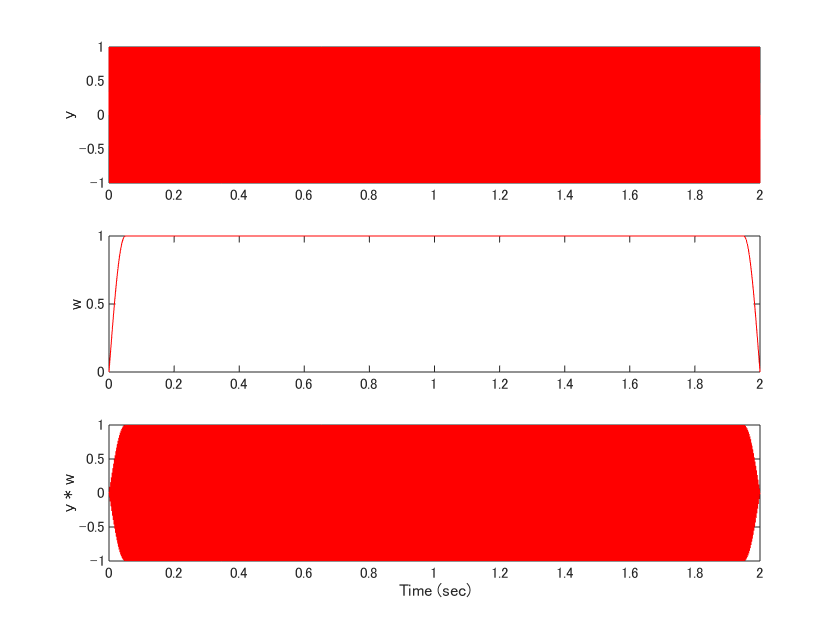

rw = sin(linspace(0, pi/2, nw)); % 窓関数の立上り部の作成
w  = [rw, ones(1, n-nw*2), fliplr(rw)];% 窓関数の作成
yw = y.*w;% サイン波に窓関数をかける

% データのプロット
figure; 
subplot(3,1,1); plot(t,y,'r-'); ylabel('y');
subplot(3,1,2); plot(t,w,'r-'); ylabel('w');
subplot(3,1,3); plot(t,yw,'r-'); ylabel('y * w');
xlabel('Time (sec)');


% サウンドの再生
sound(yw,Fs)

ヒント：[linspace](https://jp.mathworks.com/help/matlab/ref/linspace.html), [ones](https://jp.mathworks.com/help/matlab/ref/ones.html), [fliplr](https://jp.mathworks.com/help/matlab/ref/fliplr.html), [length](https://jp.mathworks.com/help/matlab/ref/length.html)

## 純音によるメロディーの作成

応用演習：純音を連ねて、自分の好きなメロディーを作成してみよう。

Fs = 8000;
a = 0.14;
d1 = 60/74;
d2 = 120/74;
d25 = 150/74;
d0 = 30/74;
t1 = 0:1/Fs:d1;
t2 = 0:1/Fs:d2;
t0 = 0:1/Fs:d0;
t25 = 0:1/Fs:d25;

freqp = 0:1/12:1;
a2s = 110*2.^freqp;
a3s = 220*2.^freqp;
a4s = 440*2.^freqp;
a5s = 880*2.^freqp;

base = a*[sin(2*pi*t2*a2s(7)) ... % Eb
          sin(2*pi*t2*a2s(9)) ... % F
          sin(2*pi*t2*a2s(11)) ...% G
          sin(2*pi*t2*a2s(11)) ...% G
          sin(2*pi*t2*a2s(11)) ... % G
          sin(2*pi*t2*a2s(11)) ... % G
          sin(2*pi*t2*a2s(4)) ... % C
          sin(2*pi*t1*a2s(4)) ... % C
          sin(2*pi*t1*a2s(2))];   % Bb

chord = a*[sin(2*pi*t2*a3s(7))+...
           sin(2*pi*t2*a3s(11))+ ...
           sin(2*pi*t2*a4s(2)),... % Eb
           ...
           sin(2*pi*t2*a3s(9))+...
           sin(2*pi*t2*a3s(12))+ ...
           sin(2*pi*t2*a4s(4))+ ...
           sin(2*pi*t2*a4s(7)), ... % Fm7
           ...
           sin(2*pi*t2*a3s(11))+...
           sin(2*pi*t2*a3s(2))+ ...
           sin(2*pi*t2*a4s(6))+ ...
           sin(2*pi*t2*a4s(9)), ... % Gm7
           ...
           sin(2*pi*t2*a3s(11))+...
           sin(2*pi*t2*a3s(2))+ ...
           sin(2*pi*t2*a4s(6))+ ...
           sin(2*pi*t2*a4s(9)), ... % Gm7
           ...
           sin(2*pi*t2*a3s(11))+...
           sin(2*pi*t2*a3s(3))+ ...
           sin(2*pi*t2*a4s(6))+ ...
           sin(2*pi*t2*a4s(9)), ... % G7
           ...
           sin(2*pi*t2*a3s(11))+...
           sin(2*pi*t2*a3s(3))+ ...
           sin(2*pi*t2*a4s(6))+ ...
           sin(2*pi*t2*a4s(9)), ... % G7
           ...
           sin(2*pi*t2*a3s(4))+...
           sin(2*pi*t2*a3s(7))+ ...
           sin(2*pi*t2*a3s(11)),... % Cm
           ...
           sin(2*pi*t2*a3s(4))+...
           sin(2*pi*t2*a3s(7))+ ...
           sin(2*pi*t2*a3s(11))... % Cm
           ];
          
melody = a*[sin(2*pi*t0*a4s(11)) ... % G
            sin(2*pi*t0*a4s(11)) ... % G  
            sin(2*pi*t0*a4s(11)) ...% G
            sin(2*pi*t0*a4s(11)) ...% G
            sin(2*pi*t0*a4s(12)) ...% Ab
            sin(2*pi*t0*a4s(11)) ...% G
            sin(2*pi*t0*a4s(12)) ...% Ab
            sin(2*pi*t2*a5s(2)) ...% Bb
            sin(2*pi*t2*0) ...% Bb            
            sin(2*pi*t0*a5s(2)) ... % Bb
            sin(2*pi*t0*a5s(2)) ... % Bb 
            sin(2*pi*t0*a5s(3)) ...% B
            sin(2*pi*t0*a5s(3)) ...% B
            sin(2*pi*t0*a5s(3)) ...% B
            sin(2*pi*t0*a5s(3)) ...% B
            sin(2*pi*t0*a4s(11)) ...% G
            sin(2*pi*t0*a4s(9)) ... % F
            sin(2*pi*t0*a4s(11)) ...% G
            sin(2*pi*t0*a4s(9)) ...% F
            sin(2*pi*t0*a4s(7)) ...% Eb
            sin(2*pi*t0*a4s(6)) ...% D
            sin(2*pi*t25*a4s(7))]; % Eb            

base = base(1:length(chord));
melody = melody(1:length(chord));

sound(chord+base+melody, Fs)